clear
close all

## Loading and initializing data

PPGraw = importdata('Rec/1/BVP.csv');
ACCraw = importdata('Rec/1/ACC.csv');

start_posix = ACCraw(1,1);
start_datetime = datetime(start_posix,'convertfrom','posixtime','timezone','Europe/Rome'); 
fs_ACC = ACCraw(2,1);
ACC = ACCraw(3:end,:)/64;
t_ACC_sec = (0:length(ACC(:,1))-1)/fs_ACC;
t_ACC_posix = t_ACC_sec + start_posix;
t_ACC_datetime = seconds(t_ACC_sec) + start_datetime;
ACCx = ACC(:,1);
ACCy = ACC(:,2);
ACCz = ACC(:,3);
ACC_norm = getNormXYZ(ACC);

% ONLY FOR SUB 6 (data cleaning)
% probe = datetime('04-Jun-2019 18:00','timezone','Europe/Rome');
% i = find(t_ACC_datetime == probe);
% ACCz = ACCz(1:i); ACCy = ACCy(1:i); ACCx = ACCx(1:i);
% t_ACC_datetime = t_ACC_datetime(1:i);
% t_ACC_sec = t_ACC_sec(1:i);
% ACC_norm = ACC_norm(1:i);

## Sleep detection algorithm ---- Van Hees

Steps 1-5 

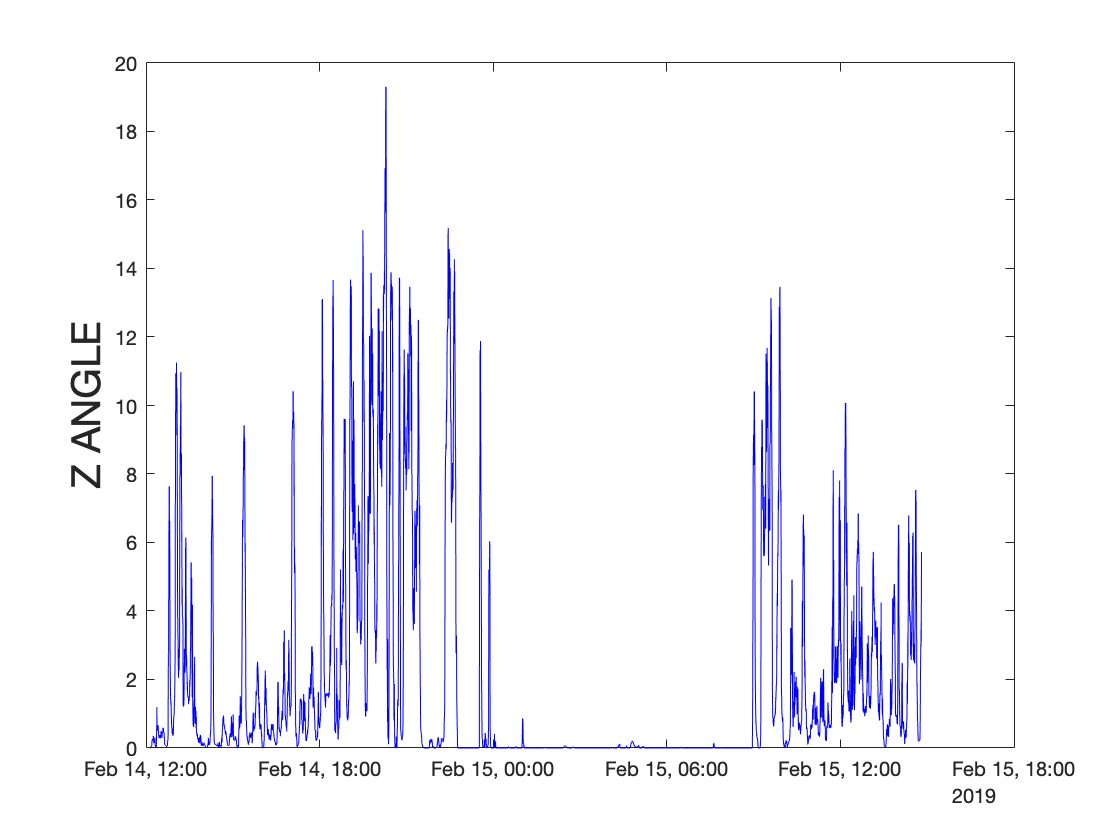

n = 5*fs_ACC; % number of samples in a 5 seconds window

z1_angle = atan( movmedian(ACCz,n) ./ ...
    ( movmedian(ACCx,n).^2 + movmedian(ACCy,n).^2) ) * 180/pi;

% averaging the z-angle every 5 consecutive seconds
z_angle_consmean = arrayfun(@(i) mean(z1_angle(i:i+n-1)),1:n:length(z1_angle)-n+1)';

% absolute differences between successive 5 seconds averages 
d = abs(diff(z_angle_consmean)); 

% 5-minute moving median (there are 60 five seconds interval in 5 minutes)
z_angle = movmedian(d, 60); 

figure(3)
t = linspace(t_ACC_datetime(1),t_ACC_datetime(end),length(z_angle));
plot(t, z_angle, 'b')
hold on
ylabel('Z ANGLE', 'FontSize', 20)
hold off

Step 6

% Computing the sleep-wake threshold
th = prctile(nonzeros(z_angle),10)*15;
sleep1 = z_angle < th;

Step 7

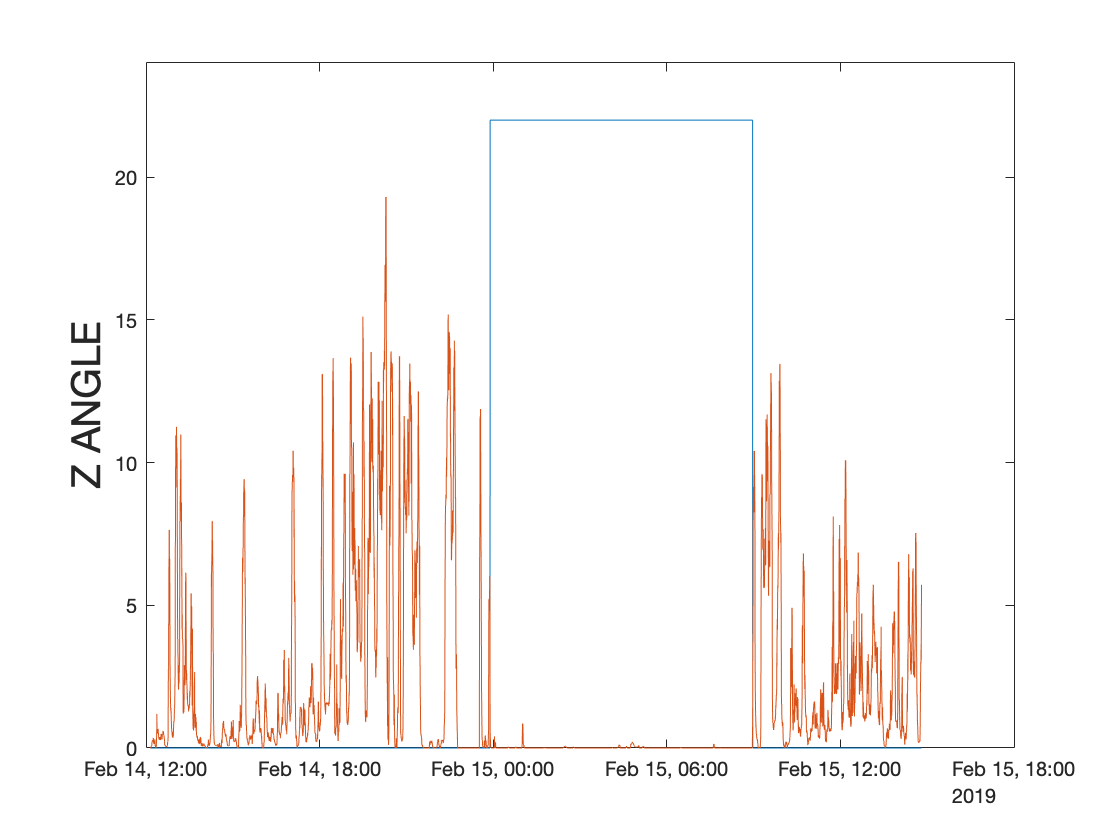

% I want to keep the entries equal to 1 only if I have consecutive ones for
% 30 minutes --> 360 five seconds intervals --> I want 360 consecutive ones
i = 1;
j = 1;
k = 1;

% I create a vector s that is structured in the following way: odd indeces
% (1, 3, 5, ...) contain the number of consecutive ones; even indeces
% (2 ,4, 6, ...) contain the number of consecutive zeros
[pks, locs] = findpeaks(double(sleep1));
s = zeros(2*length(locs)+3, 1);
while i < length(sleep1)
    while sleep1(j) == 1 && j < length(sleep1) 
        s(k) = s(k)+1;
        j = j+1;
    end
    k = k+1;
    while sleep1(j) == 0 && j < length(sleep1) 
        s(k) = s(k) + 1;
        i = i+1;
        j = j+1;
    end
    i = j;
    k = k+1;
end

% Observation blocks lasting longer than 2 hours 
ix = find(s(1:2:end) > 1440);
ix = ix*2 - 1;

% Keeping the detected intervals lasting longer than 2 hours
% I put to 0 all intervals containing ones lasting less than 2 hours
sleep = [zeros(sum(s(1:ix(1)-1)),1); ones(s(ix(1)),1)];

for i = 1:length(ix)-1
    sleep = [sleep; zeros(sum(s(ix(i)+1:ix(i+1)-1)),1); ones(s(ix(i+1)),1)];
end
sleep = [sleep; zeros(sum(s(ix(end)+1:end)),1)];

figure(4)
plot(t(1:end-1),sleep*22)
ylim([0 24])
hold on 
plot(t, z_angle)
ylabel('Z ANGLE', 'FontSize', 20)
hold off

Step 8

% Evaluate the length of the time gaps between the observation blocks 
% identified by step 7, if the duration is less than 10 minutes (= 120 five 
% seconds intervals) then count these gaps towards the identified blocks

i = 1;
j = 1;
k = 1;
[pks, locs] = findpeaks(double(sleep));
r = zeros(2*length(locs)+2, 1);

% Same idea as before
while i < length(sleep)
    while sleep(j) == 0 && j < length(sleep) 
        r(k) = r(k)+1;
        j = j+1;
    end
    k = k+1;
    while sleep(j) == 1 && j < length(sleep) 
        r(k) = r(k) + 1;
        i = i+1;
        j = j+1;
    end
    i = j;
    k = k+1;
end

ix = find(r(1:2:end) < 120); % 10 minutes
ix = ix*2 - 1;

if not(isempty(ix))
    m = sum(r(1:ix(1)-1)) + 1;
    sleep(m:m+r(ix(1))) = 1;
    for i = 1:length(ix)-1
        m = sum(r(1:ix(i+1)-1)) + 1;
        sleep(m:m+r(ix(i+1))) = 1;
    end
end

figure(5)
plot(t(1:end-1),sleep*22)
ylim([0 24])
hold on 
plot(t, z_angle)
ylabel('Z ANGLE', 'FontSize', 20)
hold off

## PPG - division in windows of sleep-wake

Sleep window selection

% Shorter sleep window among all subjects: Subject 8
load('l_min.mat'); % 6 hours, 24 minutes, 40 seconds

% PPG signal
fs_PPG = PPGraw(2);
PPG = PPGraw(3:end);
t_PPG = (0:length(PPG)-1) / fs_PPG; % seconds
t_PPG_posix = t_PPG + start_posix;
t_PPG_datetime = seconds(t_PPG) + start_datetime;

% ONLY FOR SUB 6 (data cleaning)
% probe = datetime('04-Jun-2019 18:00','timezone','Europe/Rome');
% i = find(t_PPG_datetime == probe);
% PPG = PPG(1:i);
% t_PPG_datetime = t_PPG_datetime(1:i);

tt = linspace(t_ACC_sec(1), t_ACC_sec(end), length(sleep));
ix_sleep = find(sleep);
t_sleep_start = tt(ix_sleep(1)); % seconds
t_sleep_end = tt(ix_sleep(end)); % seconds

% I need to do this because PPG recording and ACC recording do not have the
% same duration!!
[~,a]=min(abs(t_PPG-t_sleep_start));
[~,b]=min(abs(t_PPG-t_sleep_end));

PPG_sleep = PPG(a:b);
t1 = seconds(t_sleep_start) + start_datetime; 
t2 = seconds(t_sleep_end) + start_datetime;
t_sleep = linspace(t1, t2, length(PPG_sleep));

% Selecting a sleep window of 6h24min40sec at the center 
L = length(PPG_sleep)-1;
t_sleep = t_sleep((L-l_min)/2:(L+l_min)/2-1);
PPG_sleep = PPG_sleep((L-l_min)/2:(L+l_min)/2-1);

t1 = t_sleep(1); % start sleep datetime
t2 = t_sleep(end); % end sleep datetime

Wake window selection

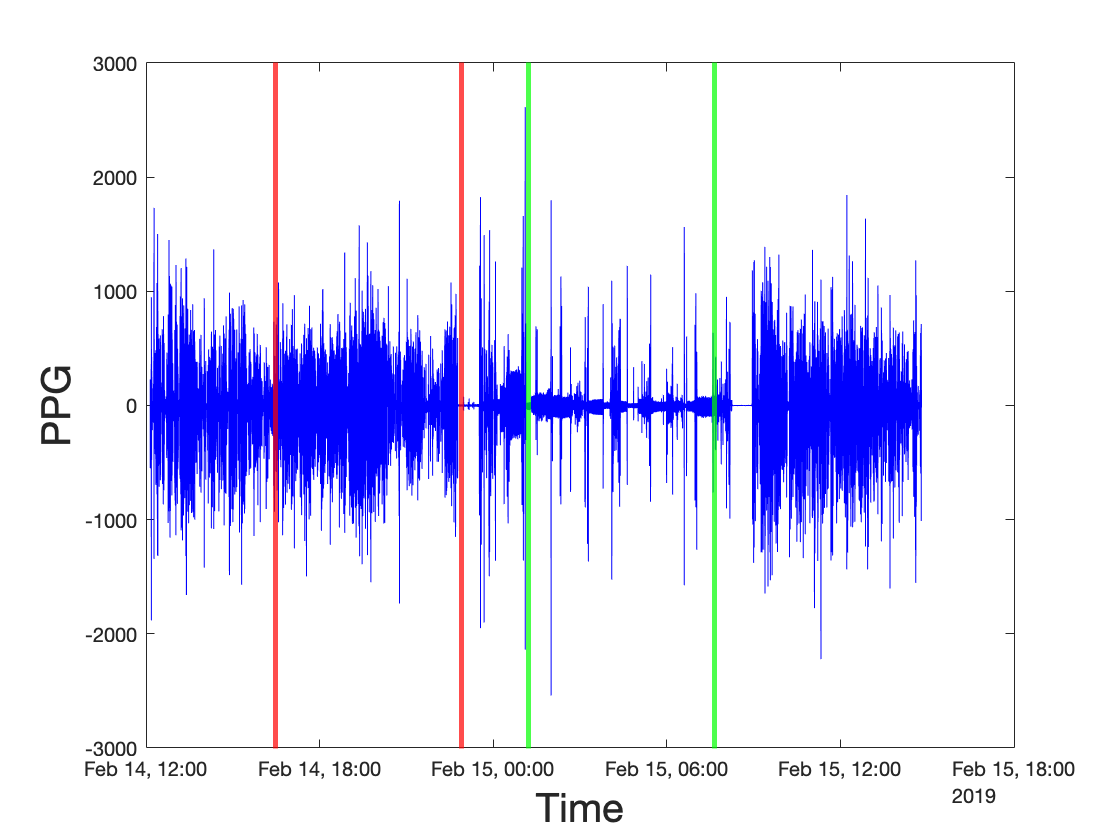

% Depending on the signal I can select this window before or after the
% sleep window

% Before the sleep window
t_wake_end = t_sleep_start - 3600; % 1 hour before sleep
[~,d] = min(abs(t_PPG-t_wake_end));
c = d-(length(PPG_sleep)-1);
t_wake_start = t_PPG(c);

% After the sleep window
% t_wake_start = t_sleep_end + 3600; % 1 hour after sleep
% [~,d] = min(abs(t_PPG-t_wake_end))
% d = c+(length(PPG_sleep)-1);
% t_wake_end = t_PPG(d);

PPG_wake = PPG(c:d);
t3 = seconds(t_wake_start) + start_datetime;
t4 = seconds(t_wake_end) + start_datetime;
t_wake = linspace(t3, t4, length(PPG_sleep));

figure 
plot(t_PPG_datetime, PPG, 'b')
hold on 
xline(t1, 'g', 'Linewidth', 2.5); xline(t2, 'g', 'Linewidth', 2.5)
xline(t3, 'r', 'Linewidth', 2.5); xline(t4, 'r', 'Linewidth', 2.5)
xlabel('Time', 'FontSize', 20)
ylabel('PPG', 'FontSize', 20)
hold off

In this section the signal quality algorithm (provided by Serena Moscato) was used, to derive reliable pulses

## HRV analysis

Quick look at the data of a single subject

IBI_sleepraw = load('IBI_sleep1_raw.mat');
IBI_sleepraw = IBI_sleepraw.IBI_sleep1_raw;
IBI_wakeraw = load('IBI_wake1_raw.mat');
IBI_wakeraw = IBI_wakeraw.IBI_wake1_raw;

IBI_data = [IBI_sleepraw IBI_wakeraw];
p1 = repmat({'Sleep'},length(IBI_sleepraw),1);
p2 = repmat({'Wake'},length(IBI_wakeraw),1);
pp = [p1; p2];
boxplot(IBI_data, pp)

As we can see from the boxplots, we have several outliers (IBIs of 3 seconds are statistically impossible). For this reason, to further clean the signal, we can think of setting a threshold to eliminate the outliers. We can consider outliers those values greater than Q3 + 3*IQR or smaller than Q1- 3*IQR (extreme outliers)

## Extraction of HRV features for all subjects

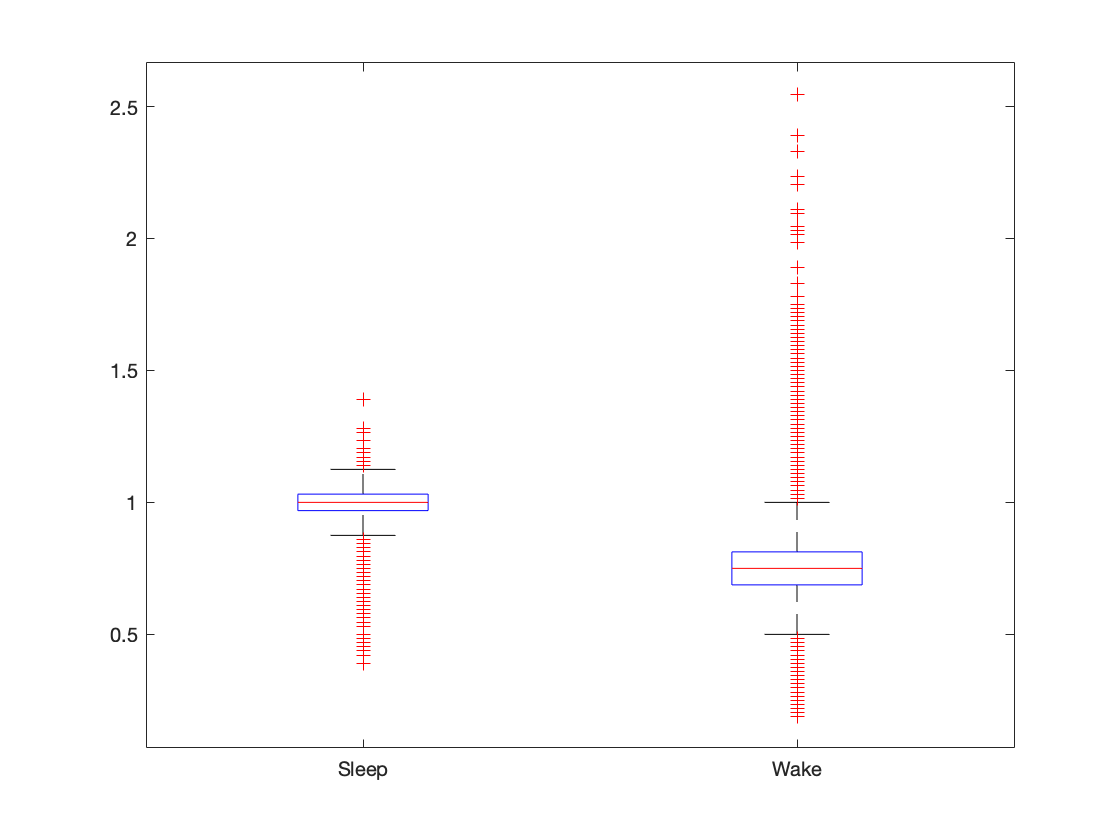

HR_sleep = [];
HR_wake = [];
SDNN_sleep = [];
SDNN_wake = [];

RMSSD_sleep = [];
RMSSD_wake = [];

aLF_sleep = [];
aHF_sleep = [];
LFHF_ratio_sleep = [];
aLF_wake = [];
aHF_wake = [];
LFHF_ratio_wake = [];

SD1_IBI_sleep = [];
SD2_IBI_sleep = [];
SD1_IBI_wake = [];
SD2_IBI_wake = [];

for n=1:10
    
    % Loading the IBIs found with PPG signal quality algorithm
    filename1 = sprintf('IBI_sleep%d_raw',n);
    IBI_sleepraw  = load(filename1);
    IBI_sleepraw = getfield(IBI_sleepraw, filename1);
    filename2 = sprintf('IBI_wake%d_raw',n); 
    IBI_wakeraw  = load(filename2);
    IBI_wakeraw = getfield(IBI_wakeraw, filename2);
    
    % Further cleaning of the sequence
    high_th_sleep = prctile(IBI_sleepraw, 75) + 3*iqr(IBI_sleepraw);
    low_th_sleep = prctile(IBI_sleepraw, 25) - 3*iqr(IBI_sleepraw);
    
    high_th_wake = prctile(IBI_wakeraw, 75) + 3*iqr(IBI_wakeraw);
    low_th_wake = prctile(IBI_wakeraw, 25) - 3*iqr(IBI_wakeraw);
    
    IBI_sleep1 = IBI_sleepraw(IBI_sleepraw < high_th_sleep & IBI_sleepraw > low_th_sleep);
    IBI_wake1 = IBI_wakeraw(IBI_wakeraw < high_th_wake & IBI_wakeraw > low_th_wake);
    
    %% Time domain features
    % HR
    HR_sleep = [HR_sleep, mean(60 ./ IBI_sleep1)];
    HR_wake = [HR_wake, mean(60 ./ IBI_wake1)];
    
    % SDNN
    SDNN_sleep = [SDNN_sleep, std(IBI_sleep1) * 1000];
    SDNN_wake = [SDNN_wake, std(IBI_wake1) * 1000];
    
    % RMSSD
    RMSSD_sleep = [RMSSD_sleep, sqrt(mean(diff(IBI_sleep1).^2)) * 1000];
    RMSSD_wake = [RMSSD_wake, sqrt(mean(diff(IBI_wake1).^2)) * 1000];
    
    %% Frequency domain
    t_IBI_sleep1 = cumsum(IBI_sleep1);
    IBI_sleep_ms = IBI_sleep1 * 1000;
    IBI_sleep_demean = IBI_sleep_ms - mean(IBI_sleep_ms)*ones(size(IBI_sleep_ms));
    % Detrend
    IBI_sleep_detrend = detrend(IBI_sleep_demean,'linear');
    % Interpolation
    F_resample = 4; 
    T_resample = 1/F_resample; 
    t_res = t_IBI_sleep1(1):T_resample:t_IBI_sleep1(end); 
    IBI_sleep_resample = interp1(t_IBI_sleep1,IBI_sleep_detrend,t_res);
    % High pass filter
    ordr     = 6;
    ft       = 0.02; %[Hz] Cutoff frequency
    Wn_HP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_HP,'high');
    IBI_HP   = filtfilt(b,a,IBI_sleep_resample);
    % Low pass filter
    ordr     = 6;
    ft       = 0.4; %[Hz] Cutoff frequency
    Wn_LP       = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_LP);
    IBI_sleep_filt = filtfilt(b,a,IBI_HP);

    window = 5*60*F_resample;
    L = length(IBI_sleep_filt); 
    NFFT = 2^nextpow2(L); % Vollmer M. 2015 "A robust, simple and reliable measure of HRV using relative RR intervals"
    [PSD,F] = pwelch(IBI_sleep_filt,[],[],NFFT,4);
    
    LF = [0.04 0.15];
    HF = [0.15 0.4];
    iLF = (round(F,2) >= LF(1)) & (round(F,2) <= LF(2));
    aLF_sleep  = [aLF_sleep, trapz(F(iLF),PSD(iLF))];
    iHF = (round(F,2) >= HF(1)) & (round(F,2) <= HF(2));
    aHF_sleep  = [aHF_sleep, trapz(F(iHF),PSD(iHF))];
    i_TP = (round(F,2) >= LF(1)) & (round(F,2) <= HF(2)); 
    TP   = trapz(F(i_TP),PSD(i_TP));
    % Normalized values of the spectral bands
    nu_LF = aLF_sleep / TP * 100; 
    nu_HF = aHF_sleep / TP * 100;
    
    LFHF_ratio_sleep = [LFHF_ratio_sleep, aLF_sleep(n)/aHF_sleep(n);];
    
    % f-domain, wake
    t_IBI_wake1 = cumsum(IBI_wake1);
    IBI_wake_ms = IBI_wake1 * 1000;
    IBI_wake_demean = IBI_wake_ms - mean(IBI_wake_ms)*ones(size(IBI_wake_ms));
    % Detrend
    IBI_wake_detrend = detrend(IBI_wake_demean,'linear');
    % Interpolation
    F_resample = 4; 
    T_resample = 1/F_resample; 
    t_res = t_IBI_wake1(1):T_resample:t_IBI_wake1(end); 
    IBI_wake_resample = interp1(t_IBI_wake1,IBI_wake_detrend,t_res);
    % High pass filter
    ordr     = 6;
    ft       = 0.02; %[Hz] Cutoff frequency
    Wn_HP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_HP,'high');
    IBI_HP   = filtfilt(b,a,IBI_wake_resample);
    % Low pass filter
    ordr     = 6;
    ft       = 0.4; %[Hz] Cutoff frequency
    Wn_LP       = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_LP);
    IBI_wake_filt = filtfilt(b,a,IBI_HP);
    
    window = 5*60*F_resample;
    L = length(IBI_wake_filt); 
    NFFT = 2^nextpow2(L); % Vollmer M. 2015 "A robust, simple and reliable measure of HRV using relative RR intervals"
    [PSD,F] = pwelch(IBI_wake_filt,[],[],NFFT,4);
    
    iLF = (round(F,2) >= LF(1)) & (round(F,2) <= LF(2));
    aLF_wake  = [aLF_wake, round(trapz(F(iLF),PSD(iLF)))];
    iHF = (round(F,2) >= HF(1)) & (round(F,2) <= HF(2));
    aHF_wake  = [aHF_wake, round(trapz(F(iHF),PSD(iHF)))];
    i_TP = (round(F,2) >= LF(1)) & (round(F,2) <= HF(2)); 
    TP   = round(trapz(F(i_TP),PSD(i_TP)));
    % Normalized values of the spectral bands
    nu_LF = aLF_wake / TP * 100; 
    nu_HF = aHF_wake / TP * 100;
    
    LFHF_ratio_wake = [LFHF_ratio_wake, aLF_wake(n)/aHF_wake(n)];
    
    %% Non-Linear domain
    x = IBI_sleep_ms;
    x(end) = [];
    y = IBI_sleep_ms;
    y(1) = [];
    L = length(x);
    SD1_IBI_sleep = [SD1_IBI_sleep, sqrt((1/L) * sum(((x - y) - mean(x - y)).^2)/2)];
    SD2_IBI_sleep = [SD2_IBI_sleep, sqrt((1/L) * sum(((x + y) - mean(x + y)).^2)/2)];
    
    % wake
    x = IBI_wake_ms;
    x(end) = [];
    y = IBI_wake_ms;
    y(1) = [];
    L = length(x);
    SD1_IBI_wake = [SD1_IBI_wake, sqrt((1/L) * sum(((x - y) - mean(x -y)).^2)/2)];
    SD2_IBI_wake = [SD2_IBI_wake, sqrt((1/L) * sum(((x + y) - mean(x + y)).^2)/2)];
end

Visual comparison across subjects between sleep and wake

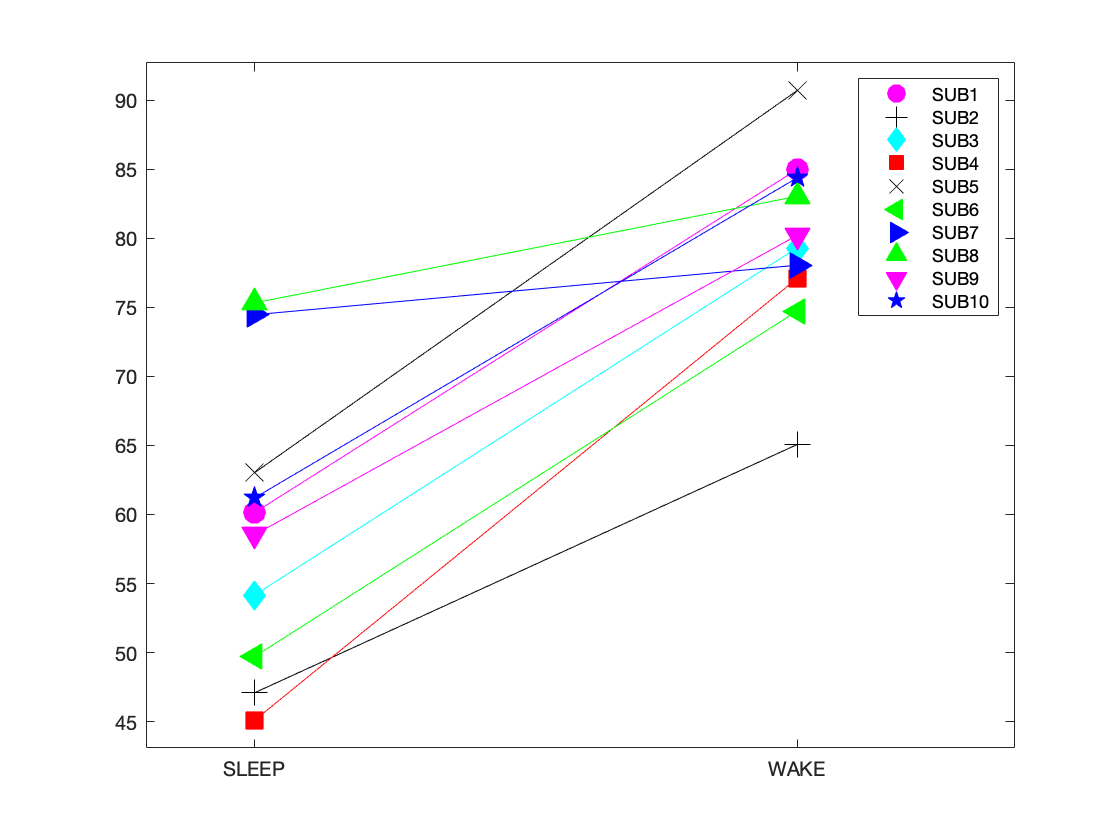

markers = ['mo'; 'k+'; 'cd'; 'rs'; 'kx'; 'g<'; 'b>'; 'g^'; 'mv'; 'bp'];

% Choose the feature to be analyzed
feature_sleep = HR_sleep;
feature_wake = HR_wake;

figure
for i = 1:10
plot(1,feature_sleep(i), markers(i,:), 'MarkerSize', 11, 'MarkerFaceColor', markers(i,1)); 
hold on
end

legend('SUB1', 'SUB2', 'SUB3', 'SUB4', 'SUB5', 'SUB6', 'SUB7', 'SUB8', 'SUB9', 'SUB10', 'AutoUpdate', 'off')

for i = 1:10
plot(2,feature_wake(i), markers(i,:), 'MarkerSize', 11, 'MarkerFaceColor', markers(i,1)); 
plot([1 2], [feature_sleep(i) feature_wake(i)], markers(i,1))
end

xticks([1 2])
xticklabels({'SLEEP', 'WAKE'})
hold off
xlim([0.8 2.4])
ylim([min(feature_sleep)-2 max(feature_wake)+2])

Correlation coefficients

corr_RMSSD_HF_sleep = corr(RMSSD_sleep', aHF_sleep')

corr_RMSSD_HF_sleep = 0.9392

corr_RMSSD_HF_wake = corr(RMSSD_wake', aHF_wake')

corr_RMSSD_HF_wake = 0.9632


corr_SDNN_LF_sleep = corr(SDNN_sleep', aLF_sleep')

corr_SDNN_LF_sleep = 0.8812

corr_SDNN_LF_wake = corr(SDNN_wake', aLF_wake')

corr_SDNN_LF_wake = 0.9594


corr_LF_SD2_sleep = corr(aLF_sleep', SD2_IBI_sleep')

corr_LF_SD2_sleep = -0.8145

corr_LF_SD2_wake = corr(aLF_wake', SD2_IBI_wake')

corr_LF_SD2_wake = 0.9375


corr_RMSSD_SD1_sleep = corr(RMSSD_sleep', SD1_IBI_sleep')

corr_RMSSD_SD1_sleep = 1.0000

corr_RMSSD_SD1_wake = corr(RMSSD_wake', SD1_IBI_wake')

corr_RMSSD_SD1_wake = 1.0000